# Modeling Mird Migration as a Flow

# Part 1: Methodology

Build and compute the Model

The equation of continuity is 


$$\frac{\partial \rho }{\partial t}=-\nabla \left(\mathit{\mathbf{v}}\rho \right)+W$$


## Load data

clear all;
load('data/Density_inference.mat','data');
load('data/Density_estimationMap','g','gd');
load('data/Flight_estimationMap','guv');
addpath('./functions/')
load coastlines;
col2=colormap(brewermap([],'Spectral'));
col2=colormap(brewermap([],'Paired'));

## Build extended grid

Build a grid `gext` with a cell more on each side of the domain (ext=extanded) in order to compute the fluxes in/out of the existing grid

gext.lat = fillmissing([nan(1,1) ;g.lat ;nan(1,1)],'linear');
gext.lon = fillmissing([nan(1,1); g.lon; nan(1,1)],'linear');
gext.nlat = numel(gext.lat);
gext.nlon = numel(gext.lon);
[gext.lat2D, gext.lon2D] = ndgrid(gext.lat,gext.lon);

The extended grid also include the time between two time step of the previous grid. Yet, because there were no time step between the last time step of the end of night (sunrise) and the first of the next day (sunset), we add one at noon every day

gext.time = sort( [g.time; g.day-.5]);

Compute different index and other stuff usefull later for the extended grid

gext.nt = numel(gext.time);
gext.day_id=nan(gext.nt,1);
gext.day_id(ismember(gext.time,g.time)) = g.day_id;
gext.day_id(isnan(gext.day_id)) = gext.day_id(find(isnan(gext.day_id))+1);
tmp=nan(g.nlm,gext.nt);
tmp(:,ismember(gext.time,g.time)) = g.NNT;
gext.NNT=nan(gext.nlat,gext.nlon,gext.nt);
gext.NNT(padarray(repmat(g.latlonmask,1,1,gext.nt),[1 1 0], false))=tmp;
gext.mask_day = (gext.NNT>-1 & gext.NNT<1);
gext.time_b=nan(gext.nt,1);
gext.time_b(ismember(gext.time,g.time)) = g.time_b;
gext.latlonmask = padarray(g.latlonmask,[1 1],false);

## Compute grid resolution

dy = lldistkm([g.lat(1) g.lon(1)],[g.lat(2) g.lon(1)]);
dx = lldistkm([g.lat2D(:,1) g.lon2D(:,1)],[g.lat2D(:,1) g.lon2D(:,2)]);
area = repmat(dx*dy,1,g.nlon);
dxext = fillmissing([NaN;dx;NaN],'linear');
areaext = fillmissing(padarray(area,[1 1],nan),'linear',1);
areaext = fillmissing(areaext,'linear',2);

The time resolution is 15 min -> 15/60 hr

dt=15/60;

Sability criteria ([https://en.wikipedia.org/wiki/Courant%E2%80%93Friedrichs%E2%80%93Lewy_condition](https://en.wikipedia.org/wiki/Courant%E2%80%93Friedrichs%E2%80%93Lewy_condition))

max(guv.u_est(:)/1000*60*60)*dt/min(dx) + max(guv.v_est(:)/1000*60*60)*dt/dy

ans = 2.7424

## Compute flight speed and density

Reshape the flight speed and density on a 3D grid (it is initially saved on a 2D grid, using only location with data) 

vy = nan(g.nlat, g.nlon, gext.nt); vx=vy; rho = vy;
tmp = repmat(g.latlonmask,1,1,gext.nt); tmp(:,:,ismember(gext.time,g.day-.5))=false;
vy(tmp) = guv.v_est/1000*60*60; % m/s -> km/h (+) north, (-) south
vx(tmp) = guv.u_est/1000*60*60; % m/s -> km/h (+) east, (-) west
tmp2 = gd.dens_est; % bird/km^2 .* repmat(area(g.latlonmask),1,g.nt); % bird

Removing data when rain. 

tmp2(g.rain(repmat(g.latlonmask,1,1,g.nt))>data.mask_rain_thr) = 0;

Rho is not density be Number of birds here. 

rho(tmp) = tmp2; % bird/km^2

We also create the same tho wihtout nan (able to comupte difference)

rho0 = rho;
rho0(isnan(rho)) = 0; % bird/km^2

## **Compute the flux **$\Phi =\mathit{\mathbf{v}}\rho$** at +/- 1/2 grid cell.**

First, add a nan layer in lat or lon direction

Phiy_pad = padarray(rho .* vy .* repmat(dx,1,g.nlon,gext.nt) ,[1 0 0],nan); % bird/km^2 * km/h *km ->  bird/h
Phix_pad = padarray(rho .* vx .* dy,[0 1 0],nan);

and then, compute the flux at +/- 1/2 even if either previous or next cells is nan. 

Phiy_h = movmean(Phiy_pad,[0 1],1,'omitnan','Endpoints','discard'); 
Phix_h = movmean(Phix_pad,[0 1],2,'omitnan','Endpoints','discard');

## Compute the delta flux / delta distance $\frac{\Delta \Phi }{\Delta \left(\mathrm{lat},\mathrm{lon}\right)}$

First, add 0 padding for the outer zone (allows to compute boundary cell)

Phiy_h_0=padarray(Phiy_h,[1 1 0],0);
Phix_h_0=padarray(Phix_h,[1 1 0],0);

 Then, replace the nan by zero to compute the change of fluxes even no fluxes on the other side (i.e. boundary cell)

Phiy_h_0(isnan(Phiy_h_0))=0;
Phix_h_0(isnan(Phix_h_0))=0;

Finally, compute the delta flux over delta distance.

dPhiy = diff(Phiy_h_0,1,1);
dPhix = diff(Phix_h_0,1,2);

## Compute the variation of bird in/out each cell 

F = (dPhiy + dPhix ).*dt; % bird/h * hr -> bird

Crank-nicolson Move F at t+1/2: 

%F(F==0)=nan;
% F = movmean( F ,[0 1],3,'omitnan'); 
% F(isnan(F))=0;

F comprise both the intral change of bird and the bird going out of the area

Inner flux: remove the boundary cells

Fin = F; 
% Fin(~gext.mask_day)=0;
Fin(repmat(~gext.latlonmask,1,1,gext.nt)) = 0;

 Outer Flux. Note that Philat_h_0 and Philat_h_0 are 0 for the cell outside the domain, such at dPhilatdlat is equal to the flux at the outer cell (with the sign corresponding to the direction).

Fout.Fout = F;
% Fout(gext.mask_day)=0;
Fout.Fout(repmat(gext.latlonmask,1,1,gext.nt)) = 0;

## Compute the landing/derpature $W$

`rho0` is used (NaN replaced by 0) to account for landing as sunset and sunrise. Unit of W is [bird =bird (*15min/15min)], when (+) Birds entering the airspace (takingoff) and (-) Birds leaving the raispace (landing)

W.W = diff(rho0 .* repmat(area,1,1,gext.nt),1,3) + Fin(2:end-1,2:end-1,1:end-1);

## Smoothing of $W$ 

standard deviation of 3x0.25° = 0.75°

ntab = 15;
B = fspecial('gaussian', [ntab*2+1 ntab*2+1], 3);
%B = fspecial('disk', 3);
WW0 = padarray(g.latlonmask,[ntab ntab],'post');

fftB=fft2(circshift(padarray(B,size(WW0)-size(B),'post'),-floor(size(B)/2)));
N=ifft2(fft2(WW0).*fftB,'symmetric');
N2=ifft2(fft2(~WW0).*fftB,'symmetric');
N(N==0)=100; % whatever value
W.Ws = ifft2(fft2(padarray(W.W,[ntab ntab 0],'post')).*fftB,'symmetric')+N2.*padarray(W.W,[ntab ntab 0],'post');
W.Ws = W.Ws(1:(end-ntab),1:(end-ntab),:);
W.Ws(repmat(~g.latlonmask,1,1,gext.nt-1))=0;

## Check result

Check for a step

i=20; i=70; i=56;% i=1095;
figure('position',[0 0 1000 600]);
subplot(2,3,1); imagesc(Phix_pad(:,:,i)); set(gca,'ydir','normal'); colorbar; title('\Phi_{x}')
subplot(2,3,4); imagesc(Phiy_pad(:,:,i)); set(gca,'ydir','normal'); colorbar; title('\Phi_{y}')
subplot(2,3,2); imagesc(dPhix(:,:,i)); set(gca,'ydir','normal'); colorbar; title('\Delta\Phi_{x}/\Delta x')
subplot(2,3,5); imagesc(dPhiy(:,:,i)); set(gca,'ydir','normal'); colorbar; title('\Delta\Phi_{y}/\Delta y')
subplot(2,3,3); imagesc(rho(:,:,i+1) - rho(:,:,i)); set(gca,'ydir','normal'); colorbar; title('\rho(t+1) - \rho(t)')
subplot(2,3,6); imagesc(F(:,:,i)); set(gca,'ydir','normal'); colorbar; title('F')

Check the spatial aggregated mass balence. 

a = reshape(nansum(nansum(Fout.Fout,1),2),1,[]);
b = reshape(nansum(nansum(rho0 .* repmat(area,1,1,gext.nt),1),2),1,[]);
c = reshape(nansum(nansum(W.W,1),2),1,[]);
figure('position',[0 0 1000 200]); hold on; xlabel('time');ylabel('Error')
plot(b(2:end) - b(1:end-1) - c - a(1:end-1))

See a single timestep.

figure('position',[0 0 1000 600]);
subplot(2,3,1); imagesc( rho0(:,:,i)); title('\rho(t)');set(gca,'ydir','normal'); colorbar;
subplot(2,3,2); imagesc( rho0(:,:,i+1)); title('\rho(t+1)'); set(gca,'ydir','normal'); colorbar;
subplot(2,3,3); imagesc( rho0(:,:,i+1)-rho0(:,:,i)); title('\rho(t+1) - \rho(t)'); set(gca,'ydir','normal'); colorbar;
subplot(2,3,4); imagesc(Fin(:,:,i));  title('F_{in}'); set(gca,'ydir','normal'); colorbar;
subplot(2,3,5); imagesc(W.W(:,:,i));  title('W^{t\rightarrow t+1}=\rho(t+1) - \rho(t)+F_{in}'); set(gca,'ydir','normal'); colorbar;
subplot(2,3,6); imagesc(Fout.Fout(:,:,i));  title('F_{out}'); set(gca,'ydir','normal'); colorbar;

## Seperature the landing/landing (-) and takingoff/take-off (+)

W.landing=W.Ws; W.takingoff=W.Ws;
W.landing(W.landing>=0)=0;
W.takingoff(W.takingoff<=0)=0;
Fout.leaving=Fout.Fout; Fout.entering=Fout.Fout;
Fout.leaving(Fout.leaving>=0)=0;
Fout.entering(Fout.entering<=0)=0;

Compute daily sum

W.day.takingoff=nan(g.nlat,g.nlon,g.nat);
W.day.landing=nan(g.nlat,g.nlon,g.nat);
Fout.day.entering=nan(gext.nlat,gext.nlon,g.nat);
Fout.day.leaving=nan(gext.nlat,gext.nlon,g.nat);
F_day=nan(gext.nlat,gext.nlon,g.nat);
for i_t=1:g.nat-1
    idt=gext.day_id(1:end-1)==i_t;
    W.day.takingoff(:,:,i_t)=nansum(W.takingoff(:,:,idt),3);
    W.day.landing(:,:,i_t)=nansum(W.landing(:,:,idt),3);
    Fout.day.entering(:,:,i_t)=nansum(Fout.entering(:,:,idt),3);
    Fout.day.leaving(:,:,i_t)=nansum(Fout.leaving(:,:,idt),3);
    F_day(:,:,i_t)=nansum(F(:,:,idt),3);
end
W.day.takingoff(W.day.takingoff==0)=nan;
W.day.landing(W.day.landing==0)=nan;
W.day.W=W.day.takingoff+W.day.landing;

Only keep with sufficient data. 

knownday = ismember(datenum(g.day), unique(data.day(data.day_id)));
W.day.takingoff(:,:,~knownday)=nan;
W.day.landing(:,:,~knownday)=nan;
W.day.W(:,:,~knownday)=nan;

## Compute timeseries

Ts.W = reshape(nansum(nansum(W.W,1),2),1,[]);
Ts.landing = reshape(nansum(nansum(W.landing,1),2),1,[]);
Ts.takingoff = reshape(nansum(nansum(W.takingoff,1),2),1,[]);
Ts.Fout.entering = reshape(nansum(nansum(Fout.entering,1),2),1,[]);
Ts.Fout.leaving = reshape(nansum(nansum(Fout.leaving,1),2),1,[]);
Ts.day.landing = reshape(nansum(nansum(W.day.landing,1),2),1,[]);
Ts.day.takingoff = reshape(nansum(nansum(W.day.takingoff,1),2),1,[]);
Ts.Fout.day.entering = reshape(nansum(nansum(Fout.day.entering,1),2),1,[]);
Ts.Fout.day.leaving = reshape(nansum(nansum(Fout.day.leaving,1),2),1,[]);

Ts.day.landing(~knownday)=nan;
Ts.day.takingoff(~knownday)=nan;
Ts.Fout.day.leaving(~knownday)=nan;
Ts.Fout.day.entering(~knownday)=nan;

## Save

save('data/SinkSource2.mat','W','Fout','Ts','gext','vy','vx','rho');

Remove unused data

clear ans B col2 dP* fftB N N2 ntab Phi* tmp* WW0

# Part 2: Accumulation Map

Times serie daily

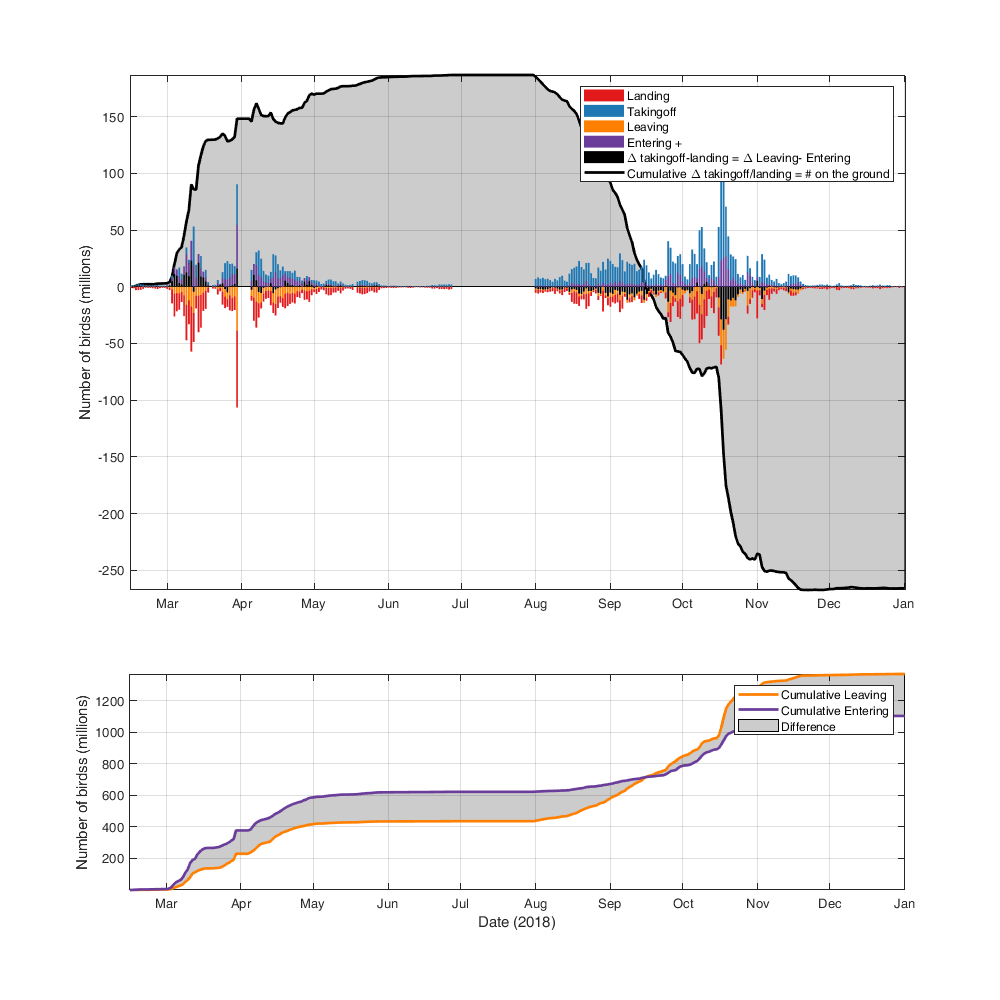

figure('position',[0 0 1000 1000]); subplot(3,1,[1 2]); box on; grid on
hold on; ylabel('Number of birdss (millions)')
% min_f = 250; max_f= 200;
% for i_b=1:numel(data.block.date)-1
%     fill([data.block.date(i_b) data.block.date(i_b) data.block.date(i_b+1) data.block.date(i_b+1)],[max_f -min_f -min_f max_f],data.block.col(i_b,:),'FaceAlpha',0.5,'EdgeColor','none')
% end
% fill([min(data.day) min(data.day) data.block.date(1) data.block.date(1)],[max_f -min_f -min_f max_f],data.block.col(4,:),'FaceAlpha',0.5,'EdgeColor','none')
% fill([data.block.date(end) data.block.date(end) max(data.day) max(data.day) ],[max_f -min_f -min_f max_f],data.block.col(4,:),'FaceAlpha',0.5,'EdgeColor','none')

fill(datenum([g.day(1); g.day; g.day(end)]),[0 cumsum((Ts.Fout.day.leaving+Ts.Fout.day.entering)/1000000,'omitnan') 0],'k','FaceAlpha',0.2);
h1=plot(datenum(g.day),cumsum((Ts.Fout.day.leaving+Ts.Fout.day.entering)/1000000,'omitnan'),'-k','linewidth',2 ,'DisplayName','Cumulative \Delta takingoff/landing = # on the ground');
h2=bar(datenum(g.day),Ts.day.landing/1000000,'FaceColor',col2(6,:),'DisplayName','Landing');
h3=bar(datenum(g.day),Ts.day.takingoff/1000000,'FaceColor',col2(2,:),'DisplayName','Takingoff');
h4=bar(datenum(g.day),Ts.Fout.day.leaving/1000000,'FaceColor',col2(8,:),'DisplayName','Leaving');
h5=bar(datenum(g.day),Ts.Fout.day.entering/1000000,'FaceColor',col2(10,:),'DisplayName','Entering +');
h6=bar(datenum(g.day),(Ts.Fout.day.leaving+Ts.Fout.day.entering)/1000000,'k','DisplayName','\Delta takingoff-landing = \Delta Leaving- Entering');
datetick('x'); axis tight; legend([h2 h3 h4 h5 h6 h1]);

subplot(3,1,3); box on; grid on
hold on; ylabel('Number of birdss (millions)')
% min_f = 0; max_f= 2000;
% for i_b=1:numel(data.block.date)-1
%     fill([data.block.date(i_b) data.block.date(i_b) data.block.date(i_b+1) data.block.date(i_b+1)],[max_f -min_f -min_f max_f],data.block.col(i_b,:),'FaceAlpha',0.5,'EdgeColor','none')
% end
% fill([min(data.day) min(data.day) data.block.date(1) data.block.date(1)],[max_f -min_f -min_f max_f],data.block.col(4,:),'FaceAlpha',0.5,'EdgeColor','none')
% fill([data.block.date(end) data.block.date(end) max(data.day) max(data.day) ],[max_f -min_f -min_f max_f],data.block.col(4,:),'FaceAlpha',0.5,'EdgeColor','none')
h1=fill(datenum([g.day ;flipud(g.day)]),-[cumsum((Ts.Fout.day.leaving)/1000000,'omitnan') fliplr(cumsum(-(Ts.Fout.day.entering)/1000000,'omitnan'))],'k','FaceAlpha',0.2,'DisplayName','Difference');
h2=plot(datenum(g.day),cumsum(-(Ts.Fout.day.leaving)/1000000,'omitnan'),'Color',col2(8,:),'linewidth',2 ,'DisplayName','Cumulative Leaving');
h3=plot(datenum(g.day),cumsum((Ts.Fout.day.entering)/1000000,'omitnan'),'Color',col2(10,:),'linewidth',2 ,'DisplayName','Cumulative Entering');
datetick('x'); xlabel('Date (2018)'); axis tight; legend([h2 h3 h1]);

Maximum Number of bird in a night

[max_takeoff,tmp] = max(Ts.day.takingoff(g.day<datetime('15-July-2018')));
max_takeoff/1000000

ans = 90.4110

g.day(tmp)

ans = datetime
   30-Mar-2018 00:00:00


[max_takeoff,tmp] = max(Ts.day.takingoff);
max_takeoff/1000000

ans = 99.1017

g.day(tmp)

ans = datetime
   18-Oct-2018 00:00:00


How many night to reach 50% of all derpature

tmp = Ts.day.takingoff(g.day<datetime('15-July-2018') & ~isnan(Ts.day.takingoff'));
sum( (cumsum(sort(tmp,'descend'),'omitnan') ./ nansum(tmp)) < .5) 

ans = 18

tmp = Ts.day.takingoff(g.day>datetime('15-July-2018') & ~isnan(Ts.day.takingoff'));
sum( (cumsum(sort(tmp,'descend'),'omitnan') ./ nansum(tmp)) < .5) 

ans = 27

tmp = Ts.day.takingoff( ~isnan(Ts.day.takingoff'));
sum( (cumsum(sort(tmp,'descend'),'omitnan') ./ nansum(tmp)) < .5) 

ans = 45

Accumulation of bird in Spring

spring_entering = nansum(Ts.Fout.day.entering(g.day<datetime('15-July-2018'))/1000000)

spring_entering = 623.1028

spring_leaving = nansum(Ts.Fout.day.leaving(g.day<datetime('15-July-2018'))/1000000)

spring_leaving = -436.4444

spring_delta = spring_entering + spring_leaving

spring_delta = 186.6584

Accumulation (or dissipation) of bird in Autumns

autumn_entering = nansum(Ts.Fout.day.entering(g.day>datetime('15-July-2018'))/1000000)

autumn_entering = 481.5620

autumn_leaving = nansum(Ts.Fout.day.leaving(g.day>datetime('15-July-2018'))/1000000)

autumn_leaving = -934.0337

autumn_delta = autumn_entering + autumn_leaving

autumn_delta = -452.4717

Recrutement = Flux out/Flux in = Bird in + reproduction / Bird in

-autumn_delta / spring_delta

ans = 2.4241

nancov(Ts.Fout.day.entering',Ts.Fout.day.leaving')
nancov(Ts.Fout.day.entering(2:end)',Ts.Fout.day.leaving(1:end-1)')
nancov(Ts.Fout.day.entering(1:end-1)',Ts.Fout.day.leaving(2:end)')

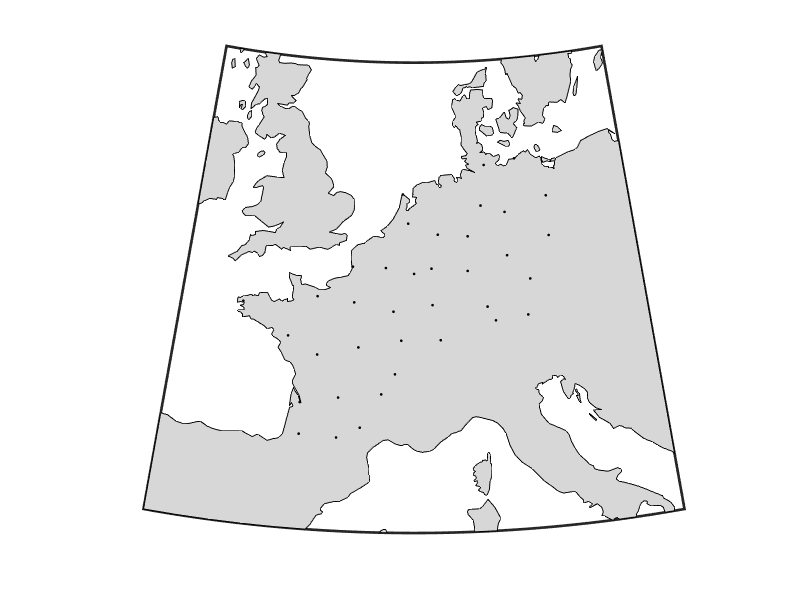

%% Illustration of the fluxes (Figure 1)
files={'gt30w020n90'};%,'gt30e020n90'}; % ,'gt30e020n40','gt30w020n40'
[DEM,GeoCellRef] = geotiffread(['data/' files{1}]);
GeoCellRef_lon = linspace(GeoCellRef.LongitudeLimits(1),GeoCellRef.LongitudeLimits(2),GeoCellRef.RasterSize(2));
GeoCellRef_lat = linspace(GeoCellRef.LatitudeLimits(2),GeoCellRef.LatitudeLimits(1),GeoCellRef.RasterSize(1));
[GeoCellRef_LON,GeoCellRef_LAT] = meshgrid(GeoCellRef_lon,GeoCellRef_lat);
id_lat = GeoCellRef_lat>g.lat(1)-3 & GeoCellRef_lat<g.lat(end)+3;
id_lon = GeoCellRef_lon>g.lon(1)-3 & GeoCellRef_lon<g.lon(end)+3;
DEM(DEM>-5000&DEM<=0)=0;

figure('position',[0 0 800 600]);hold on
h = worldmap([g.lat(1)-3 g.lat(end)+3], [g.lon(1)-3 g.lon(end)+3]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
%geoshow(GeoCellRef_LAT(id_lat,id_lon), GeoCellRef_LON(id_lat,id_lon), DEM(id_lat,id_lon),'DisplayType','texturemap'); demcmap(DEM(id_lat,id_lon))
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255);
plotm([data.lat],[data.lon],'.k')

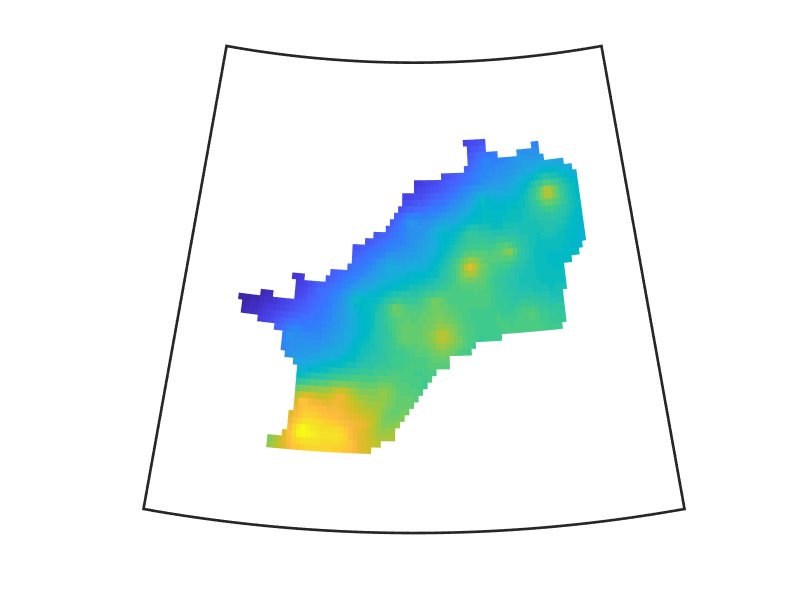

figure('position',[0 0 800 600]);hold on
h = worldmap([g.lat(1)-3 g.lat(end)+3], [g.lon(1)-3 g.lon(end)+3]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
tmp = sum(rho,3,'omitnan'); tmp(~g.latlonmask)=nan;
surfm(g.lat2D,g.lon2D, tmp)

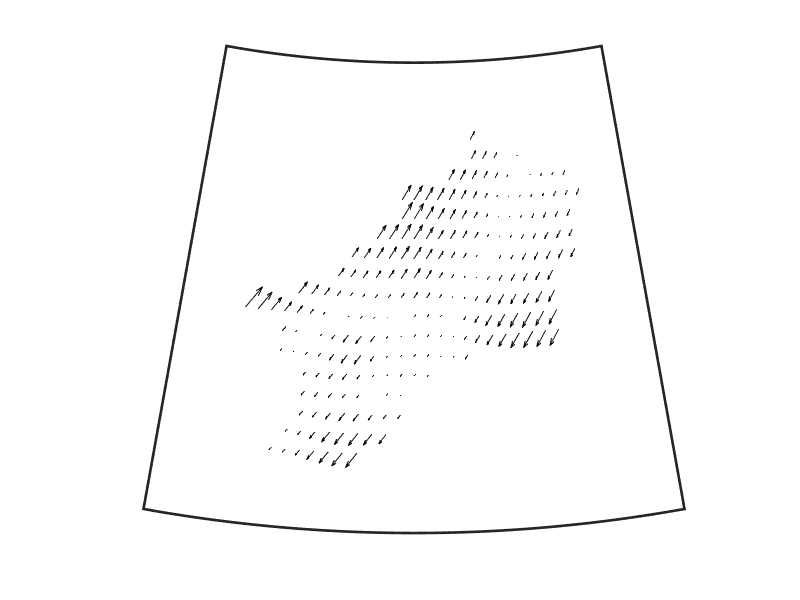

%colormap(flipud(autumn))
figure('position',[0 0 800 600]);hold on
h = worldmap([g.lat(1)-3 g.lat(end)+3], [g.lon(1)-3 g.lon(end)+3]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
tmp1 = nansum(vy,3); tmp1(~g.latlonmask)=nan;
tmp2 = nansum(vy,3); tmp2(~g.latlonmask)=nan;
quiverm(g.lat2D(1:3:end,1:3:end),g.lon2D(1:3:end,1:3:end), tmp1(1:3:end,1:3:end), tmp2(1:3:end,1:3:end),'k')

# Transect

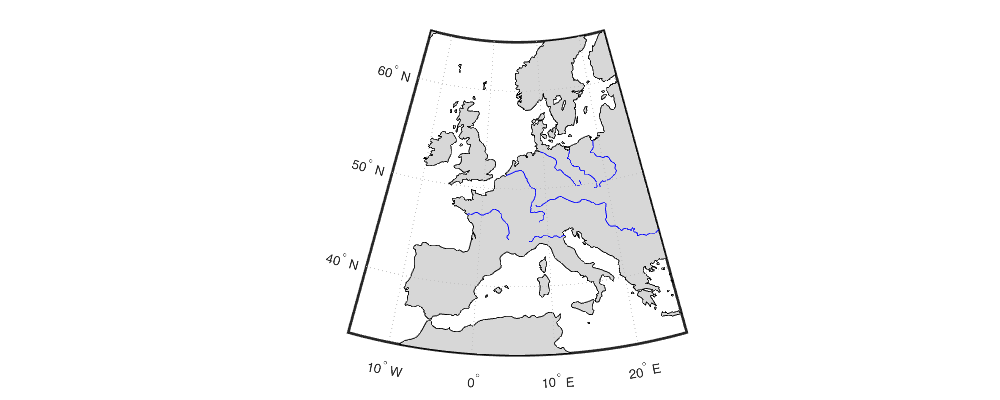

figure('position',[0 0 1000 400]);
h = worldmap([g.lat(1)-10 g.lat(end)+10], [g.lon(1)-10 g.lon(end)+10]);
%setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')

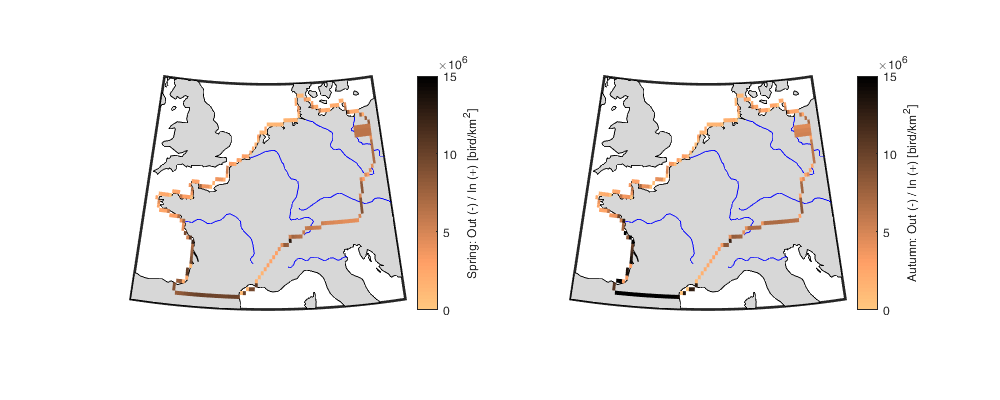


figure('position',[0 0 1000 400]);
subplot(1,2,1);
h = worldmap([g.lat(1)-1 g.lat(end)+1], [g.lon(1)-1 g.lon(end)+1]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
id = g.day_b == 1;
tmp_s = nansum(F_day(:,:,id),3);
tmp_s(tmp_s==0)=nan; tmp_s((mean(Fout.Fout>0,3)==0))=nan;
surfm([gext.lat2D gext.lat; 55.5*ones(1,gext.nlon+1)]-0.125, [gext.lon2D 14.5*ones(gext.nlat,1); gext.lon' 14.5]-0.125 ,abs(padarray(tmp_s,[1 1],nan,'post')),'Facecolor','flat'); 
c=colorbar;c.Label.String = 'Spring: Out (-) / In (+) [bird/km^2]'; caxis([0 1.5]*10^7)

subplot(1,2,2);
h = worldmap([g.lat(1)-1 g.lat(end)+1], [g.lon(1)-1 g.lon(end)+1]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
id = g.day_b == 3;
tmp_a = nansum(F_day(:,:,id),3);
tmp_a(tmp_a==0)=nan; tmp_a((mean(Fout.Fout>0,3)==0))=nan;
surfm([gext.lat2D gext.lat; 55.5*ones(1,gext.nlon+1)]-0.125, [gext.lon2D 14.5*ones(gext.nlat,1); gext.lon' 14.5]-0.125 ,abs(padarray(tmp_a,[1 1],nan,'post')),'Facecolor','flat'); 
c=colorbar;c.Label.String = 'Autumn: Out (-) / In (+) [bird/km^2]'; 
%colormap(brewermap([],'PiYG')); 
colormap(flipud(copper))
caxis([0 1.5]*10^7)

figure('position',[0 0 1000 400]);
h = worldmap([g.lat(1)-1 g.lat(end)+1], [g.lon(1)-1 g.lon(end)+1]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
tmp = randn(size(g.lat2D)); tmp(~g.latlonmask)=nan;
surfm(g.lat2D, g.lon2D, tmp); plotm(data.lat,data.lon,'.k')

## Flux per sector (15min)

transect_name={'North', 'East', 'Alpes', 'Spain' ,'Altlantic','England'};
transect(:,:,1)= [42 51 ; 43 82];
transect(:,:,2)= [20 45 ; 78 87];
transect(:,:,3)= [1 19 ; 40 84];
transect(:,:,4)= [1 9; 1 39];
transect(:,:,5) = [5 24; 1 18];
transect(:,:,6)= [25 43 ; 1 45];
sec_col={'r','b','y','g','c','k'};
cat=zeros(gext.nlat,gext.nlon);
for i_s=1:numel(transect_name)
    cat(transect(1,1,i_s):transect(1,2,i_s),transect(2,1,i_s):transect(2,2,i_s))=i_s;
end

Figure illustration sector

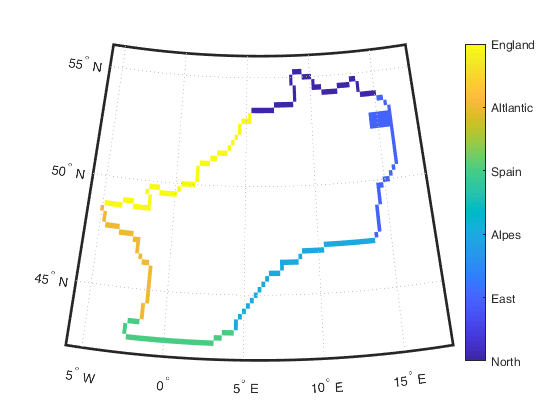

% figure; h = worldmap([g.lat(1)-1 g.lat(end)+1], [g.lon(1)-1 g.lon(end)+1]);
% setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
% %geoshow(ax, 'landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
% [DEM,GeoCellRef] = geotiffread('data/gt30w020n90');
% geoshow(DEM,GeoCellRef,'DisplayType','texturemap'); demcmap(DEM)
figure; worldmap([g.lat(1)-1 g.lat(end)+1], [g.lon(1)-1 g.lon(end)+2]);
tmp = cat; tmp(mean(Fout.Fout>0,3)<.02)=nan;
surfm([gext.lat2D gext.lat; 55.5*ones(1,gext.nlon+1)]-0.125, [gext.lon2D 14.5*ones(gext.nlat,1); gext.lon' 14.5]-0.125 ,padarray(tmp,[1 1],nan,'post'),'Facecolor','flat'); 
c=colorbar; c.Ticks=1:6; c.TickLabels=transect_name;

for i_s=1:numel(transect_name)
    tmp = Fout.Fout;
    tmp(~(repmat(cat==i_s,1,1,gext.nt-1)))=0;
    Fout.sec(:,i_s) = reshape(nansum(nansum(tmp,1),2),1,[]);
end

Flux per sector (daily)

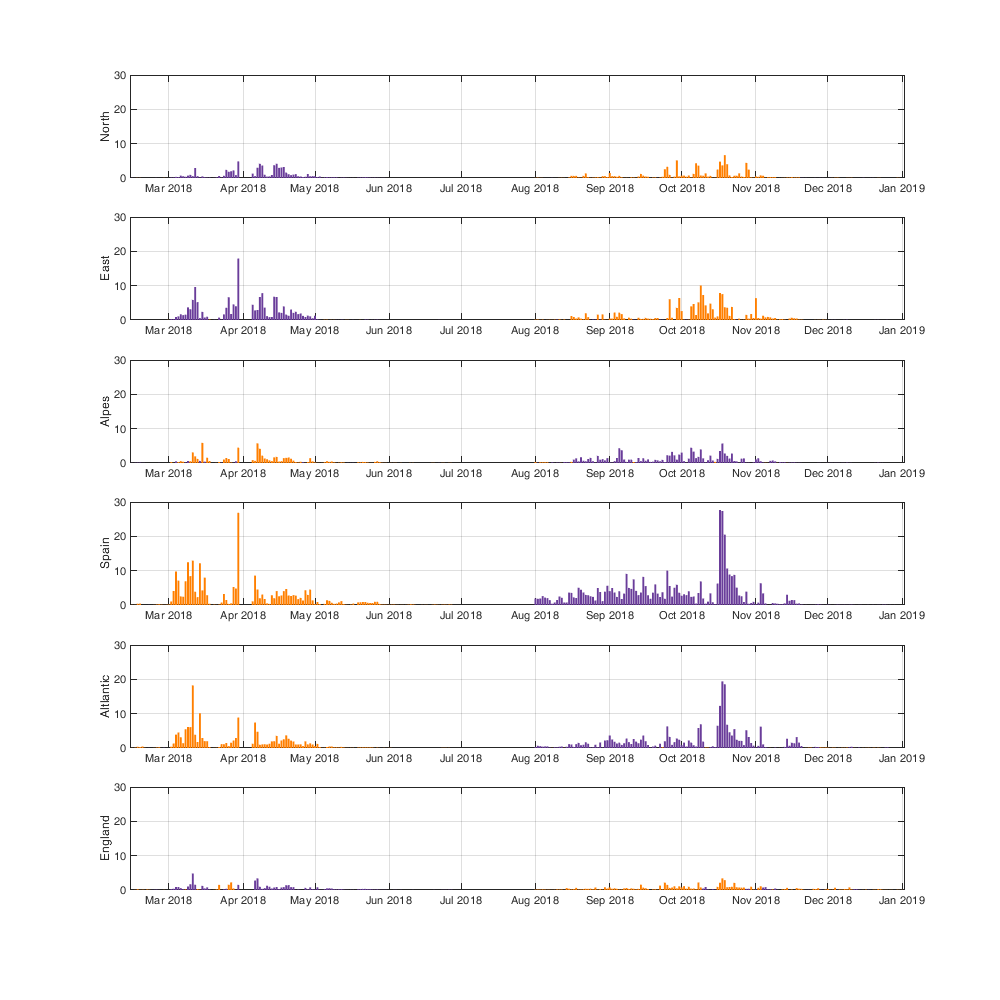

Fout.sec_day=nan(g.nat,numel(transect_name));
for i_t=1:g.nat
    idt=gext.day_id(1:end-1)==i_t;
    Fout.sec_day(i_t,:)=nansum(Fout.sec(idt,:));
end
knownday = ismember(datenum(g.day), unique(data.day(data.day_id)));
Fout.sec_day(~knownday,:)=nan;

figure('position',[0 0 1000 1000]); 
for i_s=1:numel(transect_name)
    subplot(numel(transect_name),1,i_s); hold on;
    tmp = Fout.sec_day(:,i_s)/1000000;
    tmp(tmp<0)=nan;
    bar(g.day, tmp,'FaceColor',col2(8,:));
    tmp = Fout.sec_day(:,i_s)/1000000;
    tmp(tmp>0)=nan;
    bar(g.day, -tmp,'FaceColor',col2(10,:));
    ylabel(transect_name{i_s})
    ylim([0 30])
    box on; grid on
end

Flux per sector (season)

Fout.sec_season=nan(numel(transect_name),4);
tmp = Fout.sec(g.time<datetime('2018-07-01'),:); tmp(tmp>0)=0;
Fout.sec_season(:,1)=nansum(tmp);
tmp = Fout.sec(g.time<datetime('2018-07-01'),:); tmp(tmp<0)=0;
Fout.sec_season(:,2)=nansum(tmp);
tmp = Fout.sec(g.time>datetime('2018-07-01'),:); tmp(tmp>0)=0;
Fout.sec_season(:,3)=nansum(tmp);
tmp = Fout.sec(g.time>datetime('2018-07-01'),:); tmp(tmp<0)=0;
Fout.sec_season(:,4)=nansum(tmp);

Figure

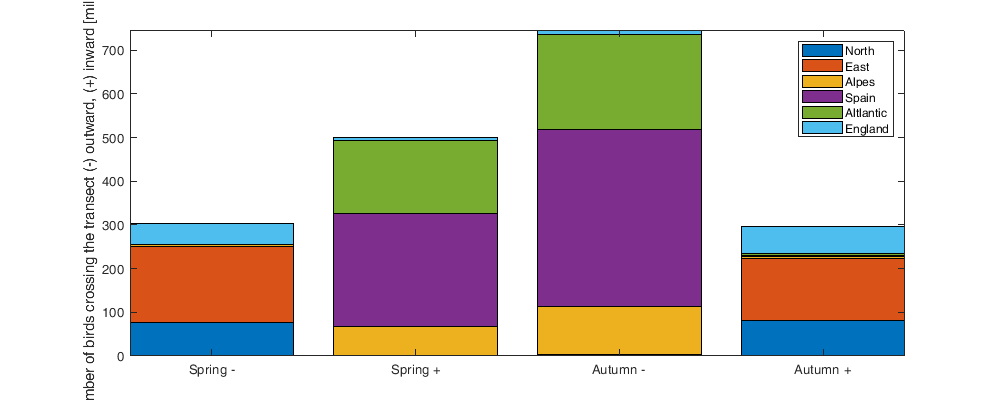

figure('position',[0 0 1000 400]); box on
bar(abs(Fout.sec_season)'/1000000,'stacked'); axis tight
xticklabels({'Spring -', 'Spring +','Autumn -','Autumn +'})
ylabel('Number of birds crossing the transect (-) outward, (+) inward [millions]')
legend(transect_name)

tmp = [sum(Fout.sec_season(:,1:2),2) sum(Fout.sec_season(:,3:4),2)]/1000000;

Spring and Autum (col) fluxes over the transects

disp(round(tmp))

   -77    81
  -172   139
    62  -105
   258  -403
   166  -215
   -40    53



Internal change

disp(round(sum(tmp)))

   197  -450



Sum of grouped transect

disp(round([sum(tmp([1 2 end],:)) ; sum(tmp([3:5],:))]))

  -289   273
   486  -724



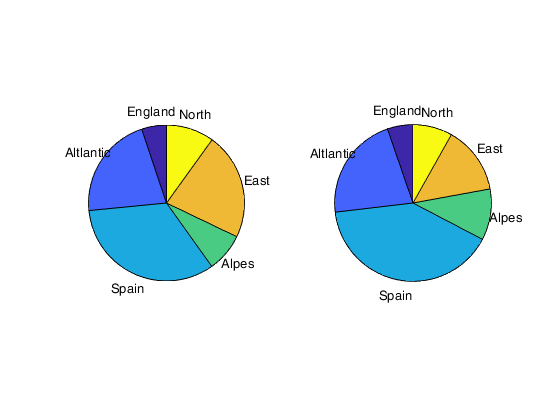

figure; subplot(1,2,1)
pie(flipud(abs(tmp(:,1))),fliplr(transect_name))
subplot(1,2,2)
pie(flipud(abs(tmp(:,2))),fliplr(transect_name))

Arrival/Departure over season

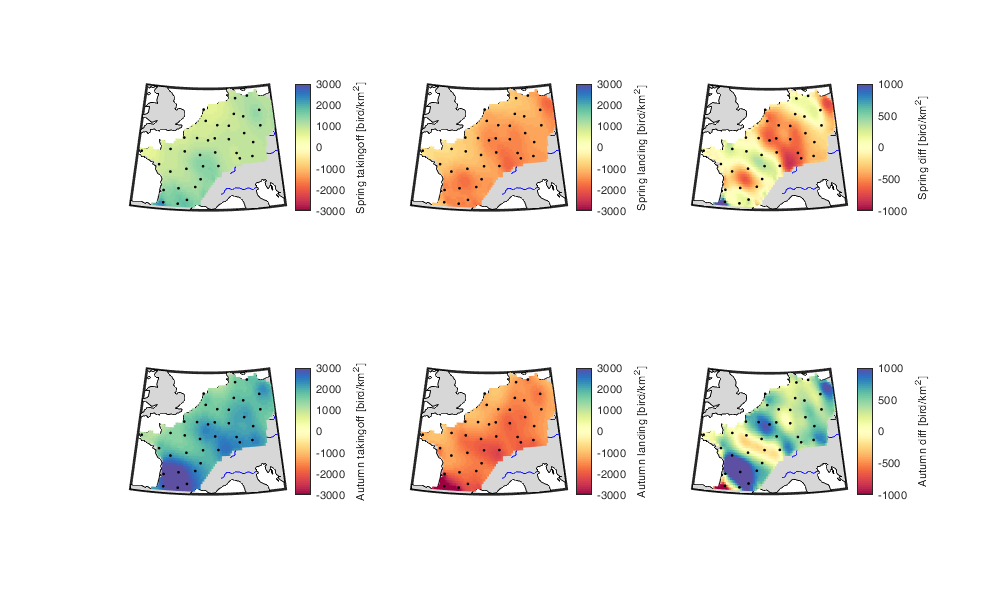

figure('position',[0 0 1000 600]); 

id = g.day<datetime('2018-07-01');
subplot(2,3,2); hold on
h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
W_tmp=nansum(W.day.landing(:,:,id),3);
W_tmp(W_tmp==0)=NaN;
surfm(g.lat2D,g.lon2D, W_tmp./area ); 
plotm(data.lat,data.lon,'.k')
c=colorbar;c.Label.String = 'Spring landing [bird/km^2]'; caxis([-3000 3000])
subplot(2,3,1); hold on
h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
W_tmp=nansum(W.day.takingoff(:,:,id),3);
W_tmp(W_tmp==0)=NaN;
surfm(g.lat2D,g.lon2D,W_tmp./area ); plotm(data.lat,data.lon,'.k')
c=colorbar;c.Label.String = 'Spring takingoff [bird/km^2]'; caxis([-3000 3000])
subplot(2,3,3); hold on
h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
W_tmp=nansum(W.day.W(:,:,id),3);
W_tmp(W_tmp==0)=NaN;
surfm(g.lat2D,g.lon2D,W_tmp./area ); plotm(data.lat,data.lon,'.k')
c=colorbar;c.Label.String = 'Spring diff [bird/km^2]'; caxis([-1000 1000])

id = g.day>datetime('2018-07-01');
subplot(2,3,5); hold on
h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
W_tmp=nansum(W.day.landing(:,:,id),3);
W_tmp(W_tmp==0)=NaN;
surfm(g.lat2D,g.lon2D,W_tmp./area ); plotm(data.lat,data.lon,'.k')
c=colorbar;c.Label.String = 'Autumn landing [bird/km^2]'; caxis([-3000 3000])
subplot(2,3,4); hold on; 
h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow( 'landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
W_tmp=nansum(W.day.takingoff(:,:,id),3);
W_tmp(W_tmp==0)=NaN;
surfm(g.lat2D,g.lon2D,W_tmp./area ); plotm(data.lat,data.lon,'.k')
c=colorbar;c.Label.String = 'Autumn takingoff [bird/km^2]'; caxis([-3000 3000])
subplot(2,3,6); hold on; 
h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow( 'landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
W_tmp=nansum(W.day.W(:,:,id),3);
W_tmp(W_tmp==0)=NaN;
surfm(g.lat2D,g.lon2D,W_tmp./area ); plotm(data.lat,data.lon,'.k')
c=colorbar;c.Label.String = 'Autumn diff [bird/km^2]'; caxis([-1000 1000])
colormap(brewermap([],'Spectral'))

Map-daily

fig=figure; 
ax = axes('Parent',fig,'units', 'normalized','position',[.05 0.15 .9 .8]);
ax1 = subplot(1,2,1);
h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow(ax1, 'landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
h1=surfm(g.lat2D,g.lon2D, W.day.takingoff(:,:,20)); colorbar;caxis([0 50000])
plotm(data.lat,data.lon,'.k')
ax2 = subplot(1,2,2);
h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow(ax2, 'landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
h2=surfm(g.lat2D,g.lon2D, -W.day.landing(:,:,20)); colorbar; caxis([0 50000])
plotm(data.lat,data.lon,'.k')
b = uicontrol('Parent',fig,'Style','slider','units', 'normalized','Position',[0.05 0.05 .9 0.05],...
              'value',1, 'min',1, 'max',size(W.day.W,3),'SliderStep', [1/size(W.day.W,3), 0.1]);
b.Callback = @(es,ed) cellfun( @(x) feval(x,es,ed), {...
    @(es,ed) set(h1,'CData', W.day.takingoff(:,:,round(es.Value+1))), ...
    @(es,ed) set(h2,'CData', -W.day.landing(:,:,round(es.Value))), ...
    @(es,ed) colorbar,...
    @(es,ed) title(ax1,['takingoff :' datestr(g.day(round(es.Value+1)))]),...
    @(es,ed) title(ax2,['landing :' datestr(g.day(round(es.Value)))]),...
   });

figure('position',[0 0 1000 600]); 
i_t=52:55;
for i_tt=1:numel(i_t)
    subplot(3,numel(i_t),i_tt); hold on
    h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    geoshow('landareas.shp', 'FaceColor', [77 77 77]./255); geoshow('worldrivers.shp','Color', 'blue')
    W_tmp=nansum(W.day.takingoff(:,:,i_t(i_tt)),3);
    W_tmp(W_tmp==0)=NaN;
    surfm(g.lat2D,g.lon2D,W_tmp./area ); 
    % plotm(nansum(W_tmp(:) .* g.lat2D(:)) ./ nansum(W_tmp(:)), nansum(W_tmp(:) .* g.lon2D(:)) ./ nansum(W_tmp(:)),'.k')
    title(datestr(g.day(i_t(i_tt))))
    colorbar
    caxis([-70 70])
    colormap(gca,brewermap([],'Spectral'))
    
    subplot(3,numel(i_t),numel(i_t)+i_tt); hold on
    h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    geoshow('landareas.shp', 'FaceColor', [77 77 77]./255); geoshow('worldrivers.shp','Color', 'blue')
    gd_tmp = nan(g.nlat, g.nlon);
    gd_tmp(g.latlonmask)=nanmean(gd.dens_est(:,i_t(i_tt)==g.day_id),2);
    gd_tmp(gd_tmp==0)=NaN;
    surfm(g.lat2D,g.lon2D,gd_tmp ); 
    % plotm(data.lat,data.lon,'.k')
    gu_tmp = nan(g.nlat, g.nlon); gv_tmp = nan(g.nlat, g.nlon);
    gu_tmp(g.latlonmask)=nanmean(guv.u_est(:,i_t(i_tt)==g.day_id),2);
    gu_tmp(gu_tmp==0)=NaN;
    gv_tmp(g.latlonmask)=nanmean(guv.v_est(:,i_t(i_tt)==g.day_id),2);
    gv_tmp(gv_tmp==0)=NaN;
    quiverm(g.lat2D(1:5:end,1:5:end),g.lon2D(1:5:end,1:5:end),gu_tmp(1:5:end,1:5:end),gv_tmp(1:5:end,1:5:end),'k')
    colorbar; %colormap(gca,brewermap([],'Spectral'))
    caxis([0 50])
    
    subplot(3,numel(i_t),2*numel(i_t)+i_tt); hold on
    h = worldmap([g.lat(1) g.lat(end)], [g.lon(1) g.lon(end)]);
    setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
    geoshow('landareas.shp', 'FaceColor', [77 77 77]./255); geoshow('worldrivers.shp','Color', 'blue')
    W_tmp=nansum(W.day.landing(:,:,i_t(i_tt)),3);
    W_tmp(W_tmp==0)=NaN;
    surfm(g.lat2D,g.lon2D,W_tmp./area ); %plotm(data.lat,data.lon,'.k')
    % plotm(nansum(W_tmp(:) .* g.lat2D(:)) ./ nansum(W_tmp(:)), nansum(W_tmp(:) .* g.lon2D(:)) ./ nansum(W_tmp(:)),'.k')
    colorbar
    caxis([-70 70])
    colormap(gca,brewermap([],'Spectral'))
end
% set(gcf,'color',[77 77 77]./255)

Map of the center of gravity

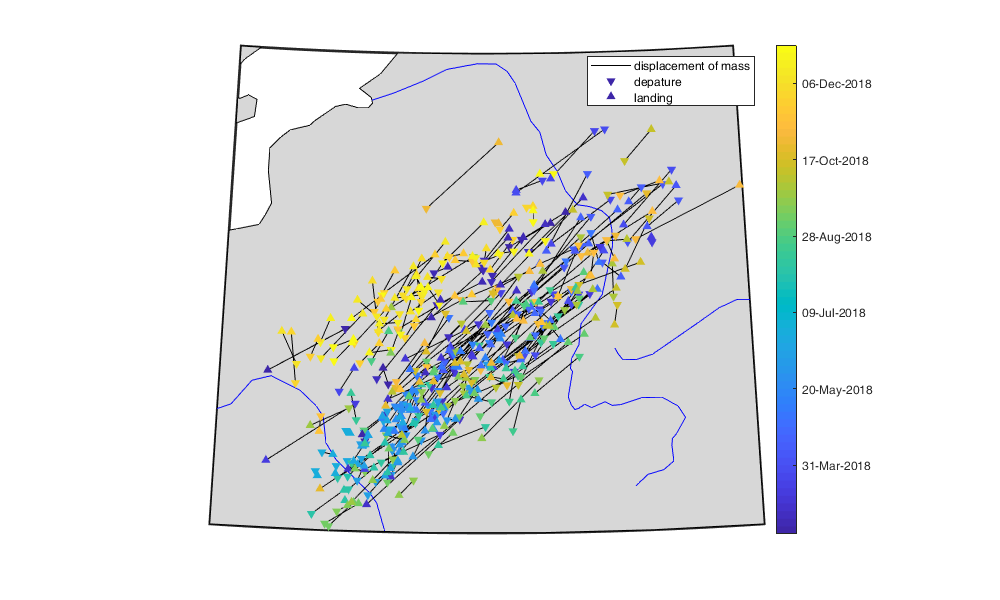

tmp = -reshape(W.day.landing(repmat(g.latlonmask,1,1,g.nat)), g.nlm, g.nat);
lat_landing = sum(tmp .* repmat(g.lat2D(g.latlonmask),1,g.nat)) ./ sum(tmp);
lon_landing = sum(tmp .* repmat(g.lon2D(g.latlonmask),1,g.nat)) ./ sum(tmp);
tmp = -reshape(W.day.takingoff(repmat(g.latlonmask,1,1,g.nat)), g.nlm, g.nat);
lat_takingoff = sum(tmp .* repmat(g.lat2D(g.latlonmask),1,g.nat)) ./ sum(tmp);
lon_takingoff = sum(tmp .* repmat(g.lon2D(g.latlonmask),1,g.nat)) ./ sum(tmp);

figure('position',[0 0 1000 600]); 
h = worldmap([46 52], [1 11]);
setm(h,'frame','on','grid','off'); set(findall(h,'Tag','MLabel'),'visible','off'); set(findall(h,'Tag','PLabel'),'visible','off')
geoshow('landareas.shp', 'FaceColor', [215 215 215]./255); geoshow('worldrivers.shp','Color', 'blue')
for i_t=1:g.nat-1
    h1=plotm([lat_takingoff(i_t)', lat_landing(i_t)], [lon_takingoff(i_t) lon_landing(i_t)'], '-k');
end
h2=scatterm(lat_landing', lon_landing',[], datenum(g.day), 'v','filled');
h3=scatterm(lat_takingoff', lon_takingoff',[], datenum(g.day),'^','filled');
legend([h1 h2 h3],{'displacement of mass','depature','landing'});
c=colorbar; c.TickLabels=datestr(c.Ticks);

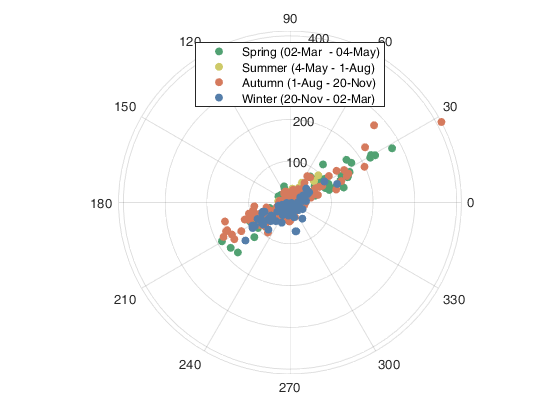


r = lldistkm([lat_landing', lon_landing'], [lat_takingoff', lon_takingoff']);
ThetaInDegrees = atan2d( (lat_landing-lat_takingoff) , (lon_landing-lon_takingoff) );
figure;
for i_b=1:numel(data.block.date)
    polarscatter(deg2rad(ThetaInDegrees(g.day_b==i_b)),r(g.day_b==i_b),[],data.block.col(i_b,:),'filled'); hold on;
end
axis tight; legend(data.block.date_str,'Location','north')

load sunrise data

val = jsondecode(fileread('sunriseset_astral\sunriseset_grid.json'));
time = datetime('01-Jan-2018 00:00:00'):datetime('01-Jan-2019 00:00:00');
g_dawn=strings(g.nlm, numel(time)); g_dusk=g_dawn; g_sunrise=g_dawn; g_sunset=g_dawn;
for i=1:numel(val)
    for j=1:numel(val{i})
        g_dawn(i,j)=val{i}{j}(1);
        g_sunrise(i,j)=val{i}{j}(2);
        g_sunset(i,j)=val{i}{j}(3);
        g_dusk(i,j)=val{i}{j}(4);
    end
end
g_dawn = datetime(g_dawn);
g_dusk = datetime(g_dusk);
g_sunset = datetime(g_sunset);
g_sunrise = datetime(g_sunrise);

[~,Locb] = ismember(dateshift(g.day,'start', 'day','nearest'),time);
gg_dawn = datenum(g_dawn(:,Locb));
gg_dusk = datenum(g_dusk(:,Locb-1));
gg_sunrise = datenum(g_sunrise(:,Locb));
gg_sunset = datenum(g_sunset(:,Locb-1));

Passage vs stop

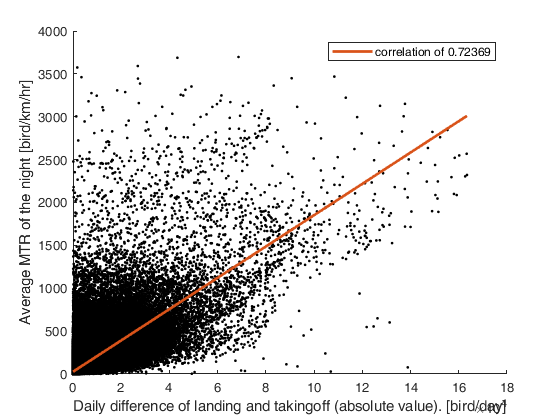

MVT = rho .* sqrt(vy.^2 + vx.^2) .* dt;
MVT_day = nan(size(W.day.W));
for i_t=1:g.nat-1
    idt=gext.day_id(1:end-1)==i_t;
    MVT_day(:,:,i_t)=nanmean(MVT(:,:,idt),3);
end

id = ~isnan(W.day.W) & ~isnan(MVT_day) & MVT_day~=0; 
figure; hold on;
scatter(abs(W.day.W(id)),MVT_day(id),'.k');
p=polyfit(abs(W.day.W(id)),MVT_day(id),1);
h2=plot(1:100:max(abs(W.day.W(id))), polyval(p,1:100:max(abs(W.day.W(id)))),'LineWidth',2);
xlabel('Daily difference of landing and takingoff (absolute value). [bird/day]')
ylabel('Average MTR of the night [bird/km/hr]')
legend(h2,['correlation of ' num2str(corr(abs(W.day.W(id)),MVT_day(id)))])

Timeseries-total space high resolution

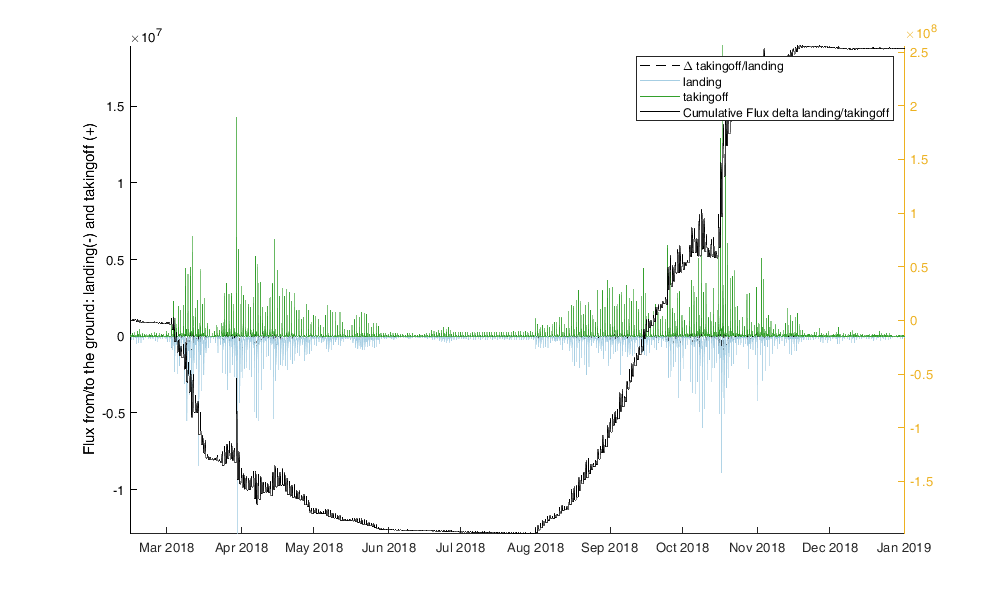

figure('position',[0 0 1000 600]);
hold on;legend
ylabel('Flux from/to the ground: landing(-) and takingoff (+)')
plot(gext.time(2:end),Ts.W,'--k','DisplayName','\Delta takingoff/landing');
plot(gext.time(2:end),Ts.landing,'Color',col2(1,:),'DisplayName','landing');
plot(gext.time(2:end),Ts.takingoff,'Color',col2(end,:),'DisplayName','takingoff');
yyaxis('right')
plot(gext.time(2:end),cumsum(Ts.W),'-k','DisplayName','Cumulative Flux delta landing/takingoff');
axis tight;

Total Number of birds in the air along the year

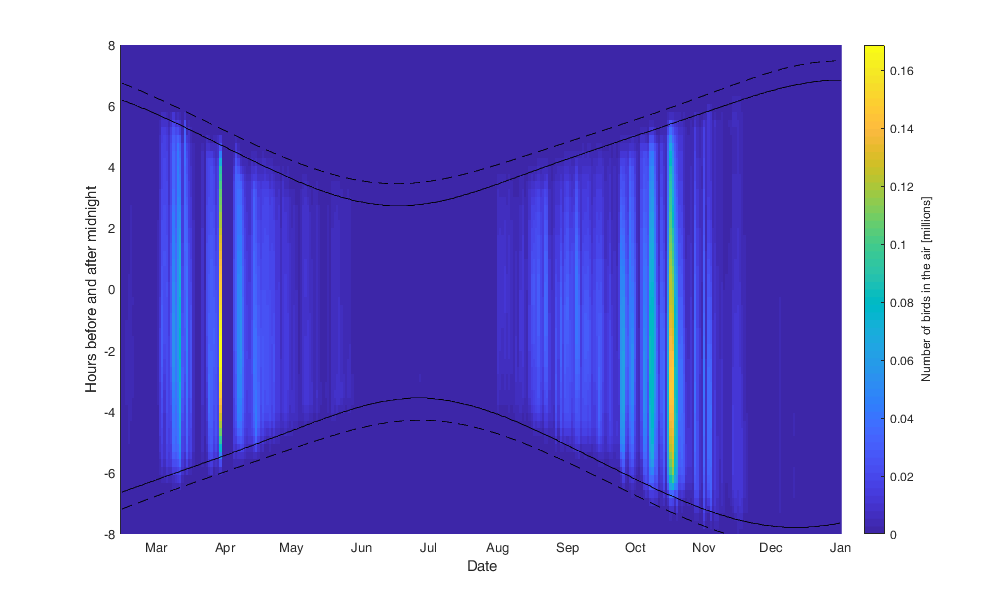

tmp = hour(gext.time)*60+minute(gext.time);
tmp(tmp>720) = tmp(tmp>720)-24*60;
id_tmp = tmp/15+12*60/15;
nb=nan(24*60/15,g.nat);
for i_t=1:g.nat
    idt=gext.day_id(1:end-1)==i_t;
    nb(id_tmp(idt),i_t)=reshape(sum(sum(rho0(:,:,idt),1),2),[],1);
end

knownday = ismember(datenum(g.day), unique(data.day(data.day_id)));
nb(:,~knownday)=nan;

figure('position',[0 0 1000 600]); hold on;
imagesc(datenum(g.day),(-12:12)*60,nb/1000000);%,'AlphaData',~isnan(nb)); 
set(gca,'ydir','normal')
datetick('x'); axis tight; ylim([-480 480]);
yticks(-480:120:480); yticklabels(-8:2:8);
xlabel('Date'); ylabel('Hours before and after midnight');
c=colorbar;c.Label.String='Number of birds in the air [millions]';

plot(datenum(g.day),hour(mean(gg_dusk,1))*60+minute(mean(gg_dusk,1))-24*60,'-k')
plot(datenum(g.day),hour(mean(gg_dawn,1))*60+minute(mean(gg_dawn,1)),'-k')
plot(datenum(g.day),mean(hour(gg_sunset)*60+minute(gg_sunset))-24*60,'--k')
plot(datenum(g.day),mean(hour(gg_sunrise)*60+minute(gg_sunrise)),'--k')

 takingoff/lading during the nights

 Over the next 15minutes. 

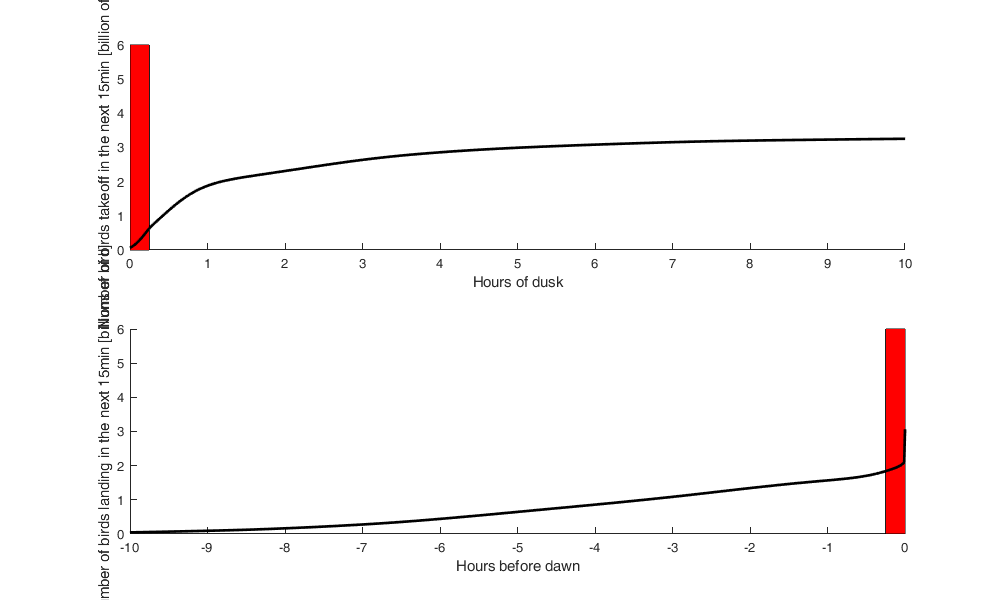

gg_dawn = datenum(g_dawn(:,Locb(gext.day_id)));
gg_dusk = datenum(g_dusk(:,Locb(gext.day_id)-1));

figure('position',[0 0 1000 600]);
tmp = reshape(W.takingoff(repmat(g.latlonmask,1,1,gext.nt-1)),g.nlm,gext.nt-1);
tmp2 = (repmat(datenum(gext.time(1:end-1)),1,g.nlm)'-datenum(gg_dusk(:,1:end-1)) ) * 24;
% figure; scatter(tmp2(:),tmp(:),'.k')
[G,ID] = findgroups(round(tmp2(:),2));
tmp_grp = splitapply(@nansum,tmp(:),G);
cumtmp_grp=cumsum(tmp_grp);
subplot(2,1,1); hold on
fill([0 15/60 15/60 0],[0 0 6 6],'r')
plot(ID+15/60,cumtmp_grp/1000000000,'k','LineWidth',2); 
xlim([0 10]); xlabel('Hours of dusk'); ylabel('Number of birds takeoff in the next 15min [billion of bird]')

tmp = reshape(-W.landing(repmat(g.latlonmask,1,1,gext.nt-1)),g.nlm,gext.nt-1);
tmp2 = (repmat(datenum(gext.time(1:end-1)),1,g.nlm)'-datenum(gg_dawn(:,1:end-1)) ) * 24;
% figure; scatter(tmp2(:),tmp(:),'.k')
[G,ID] = findgroups(round(tmp2(:),2));
tmp_grp = splitapply(@nansum,tmp(:),G);
cumtmp_grp=cumsum(tmp_grp);
cumtmp_grp(ID+15/60==0)=cumtmp_grp(end);
subplot(2,1,2); hold on;
fill([-15/60 0 0 -15/60],[0 0 6 6],'r')
plot(ID+15/60,cumtmp_grp/1000000000,'k','LineWidth',2); xlim([-10 0]); ylim([0 6])
xlabel('Hours before dawn'); ylabel(['Number of birds landing in the next 15min [billions of bird]'])